In [statistics](https://www.dummies.com/education/math/statistics/statistics-for-dummies-cheat-sheet/), we call the **correlation coefficient *****r***, and it measures the strength and direction of a linear relationship between two variables on a [scatterplot](https://www.dummies.com/education/math/statistics/how-to-interpret-a-scatterplot/). The value of *r* is always between +1 and –1.

- **Exactly** –**1.** A perfect downhill (negative) linear relationship

- –**0.70.** A strong downhill (negative) linear relationship

- –**0.50.** A moderate downhill (negative) relationship

- –**0.30.** A weak downhill (negative) linear relationship

- **0.** No linear relationship

- **+0.30.** A weak uphill (positive) linear relationship

- **+0.50.** A moderate uphill (positive) relationship

- **+0.70.** A strong uphill (positive) linear relationship

- **Exactly +1.** A perfect uphill (positive) linear relationship

the **p-value** is the probability of obtaining results at least as extreme as the observed results of a statistical [hypothesis test](https://www.investopedia.com/terms/h/hypothesistesting.asp), assuming that the [null hypothesis](https://www.investopedia.com/terms/n/null_hypothesis.asp) is correct.

- **p>0.10:** No evidence against the null hypothesis

- **0.05<p<0.10:** Weak evidence against the null hypothesis

- **0.01<p<0.05:** Moderate evidence against the null hypothesis

- **0.05<p<0.001:** Good evidence against null hypothesis

- **0.001<p<0.01: **Strong evidence against the null hypothesis

- **p<0.001:** Very strong evidence against the null hypothesis

r = corrcoef(LOT,Asp);


% scatter(LOT,Asp,"filled");
hold on;

mdl = fitlm(LOT,Asp);
[p,F] = coefTest(mdl);
mdl.Coefficients

ans = 2×4 table
                   Estimate       SE       tStat      pValue  
                   ________    ________    ______    _________

    (Intercept)      1.1094    0.076419    14.517    1.476e-14
    x1             0.015772    0.010645    1.4816      0.14962


anova(mdl,'summary')

ans = 5×5 table
                      SumSq     DF    MeanSq        F       pValue 
                     _______    __    _______    _______    _______

    Total             5.2737    29    0.18185                      
    Model            0.38338     1    0.38338     2.1951    0.14962
    Residual          4.8903    28    0.17465                      
    . Lack of fit     3.3013    19    0.17375    0.98408    0.53839
    . Pure error      1.5891     9    0.17656                      


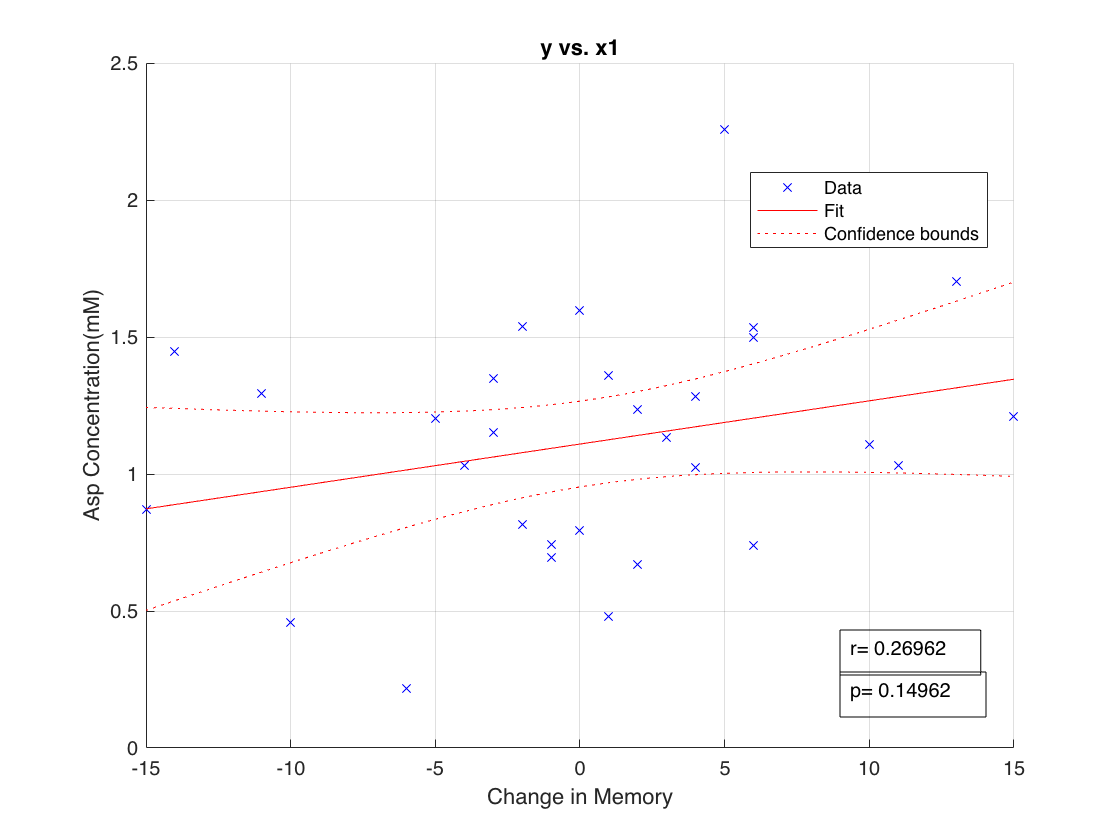

mdl.dwtest;
plot(mdl);
hold on;
xlabel('Change in Memory');
ylabel('Asp Concentration(mM)');

grid on;
annotation('textbox', [0.75, 0.1, 0.1, 0.1], 'String', "p= " + p);
annotation('textbox', [0.75, 0.15, 0.1, 0.1], 'String', "r= " + r(2,1));